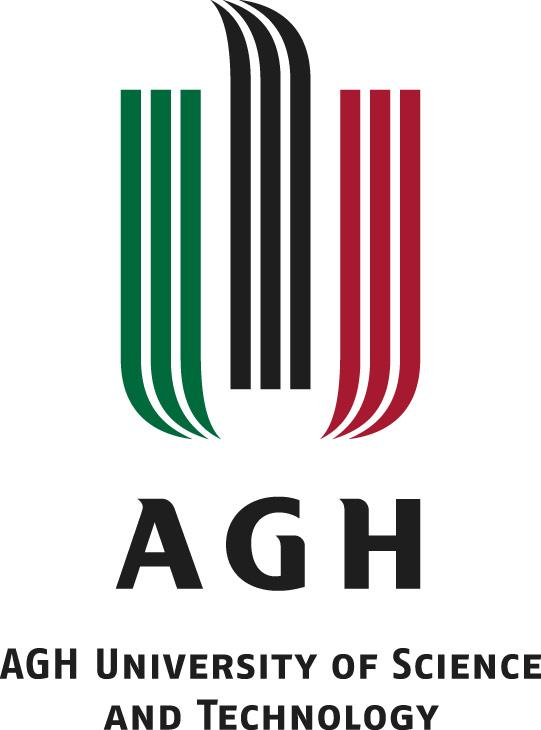

# MECHATRONIC DESIGN

# Data processing – directional and modal filtering

Mikołaj Suchoń

## 1) Time domain simulation data

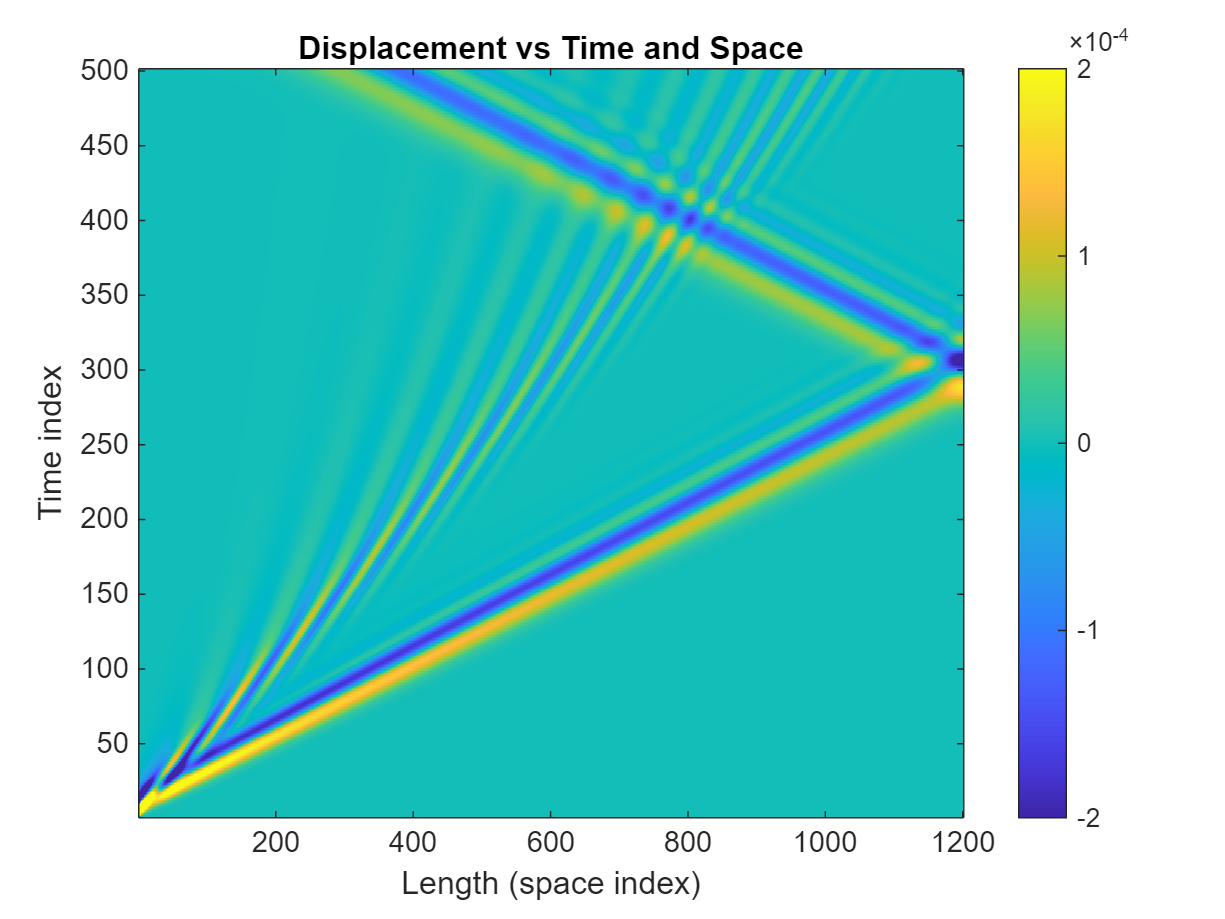

clear

% Load simulation output (time + spatial displacement data)
load simout.mat
simout = simout(2:end,:);   % remove first row (usually headers or invalid data)

% Separate time vector and displacement field
t   = simout(:,1);
out = simout(:,2:2:end);   % take displacement columns only

% Convert table to numeric array
out = table2array(out);    % out is 501 (time) x 1201 (space)

%% Visualize displacement in time and space
figure
imagesc(out)
axis xy
colorbar
clim([-2,2]/1e4)
xlabel('Length (space index)')
ylabel('Time index')
title('Displacement vs Time and Space')

In our time domain plot we can see three distinct features: a strainght line going from the beginning  of the rod to the end, the reflection. so the straight line going from the end to the beginning, and finally, the vertical rod reflections visible as the diagonal waves.

## 2) Frequency domain analysis

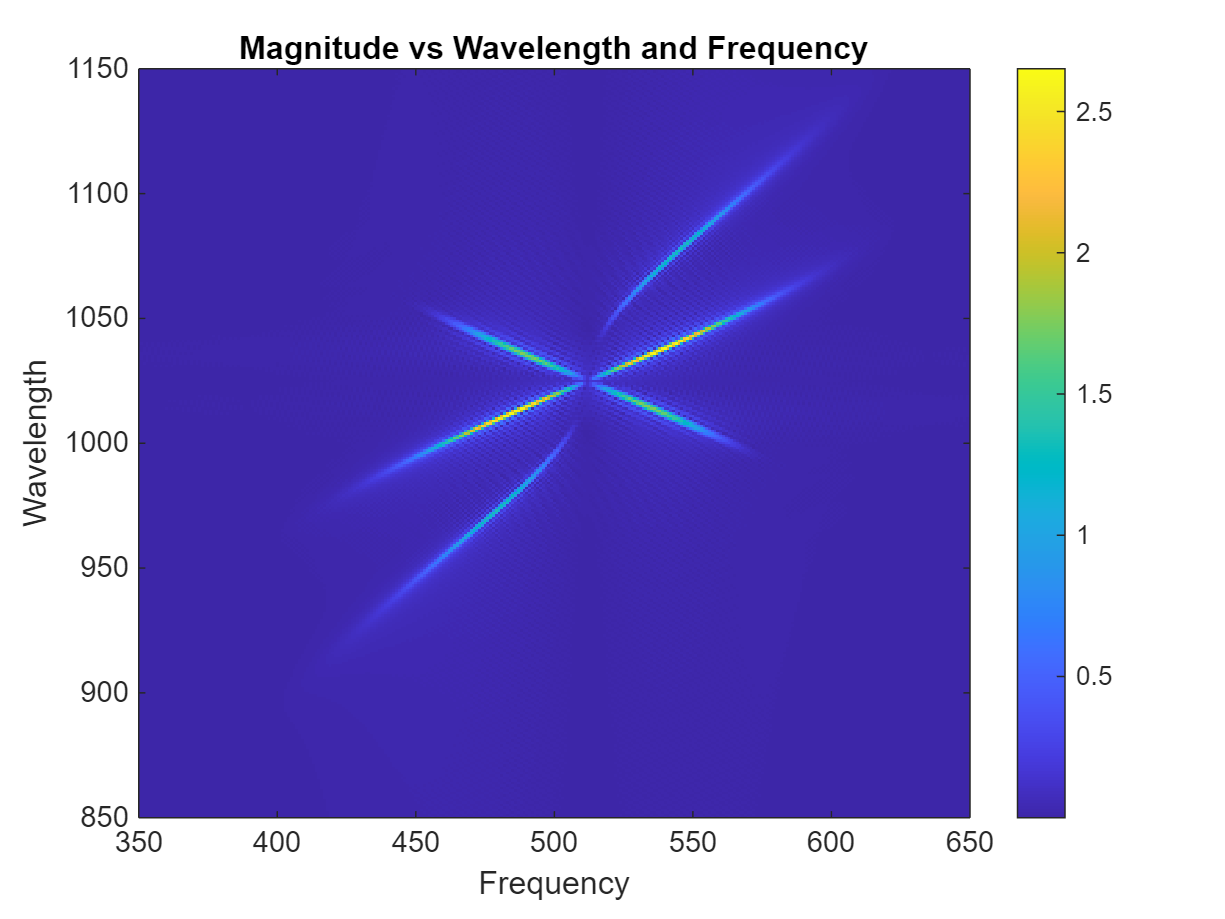

%% 2D FFT to analyze frequency–wavelength content
% Zero-padding improves frequency resolution
X = flip(fft2(out,2^10,2^11)',2);
X = fftshift(X);

figure
imagesc(abs(X))
axis xy
colorbar
xlim([350,650])
ylim([850,1150])
xlabel('Frequency')
ylabel('Wavelength')
title('Magnitude vs Wavelength and Frequency')

In the freqency domain plot we still see three distinct features (mind that the fft is symetric in the freq axis), looking at the RHS of the symmetry line: the top line going from the middle - up, the middle line going from the middle - up, the bottom line going from the middle - down.

We will try to isolate each component using masks and see it's affect on the time domain signal.

We expect the top two lined to be: the vartical wave reflecting in the rod, the horisontal wave going from the beginning to end of the rod, respectivley. The bottom line should correspond to the reflection of the horisontal wave going from the end to the beginning of the rod.

## 3) Mask creation

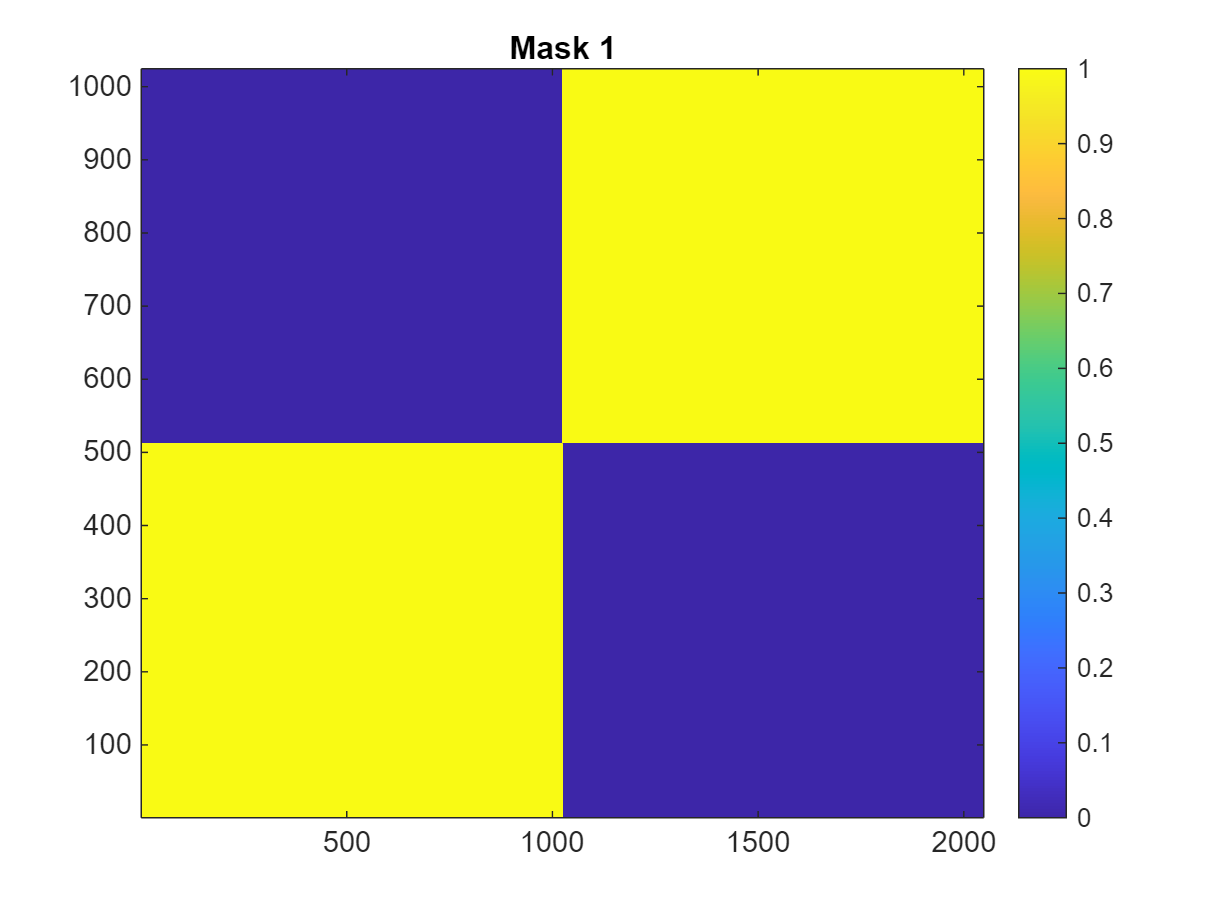

%% Create frequency-domain masks to separate wave components
one  = ones(2^9,2^10);
zero = zeros(2^9,2^10);

% Two complementary masks (quadrant-based filtering)
mask  = [one,zero; zero,one];
mask2 = [zero,one; one,zero];

figure
imagesc(mask)
title('Mask 1')
axis xy
colorbar

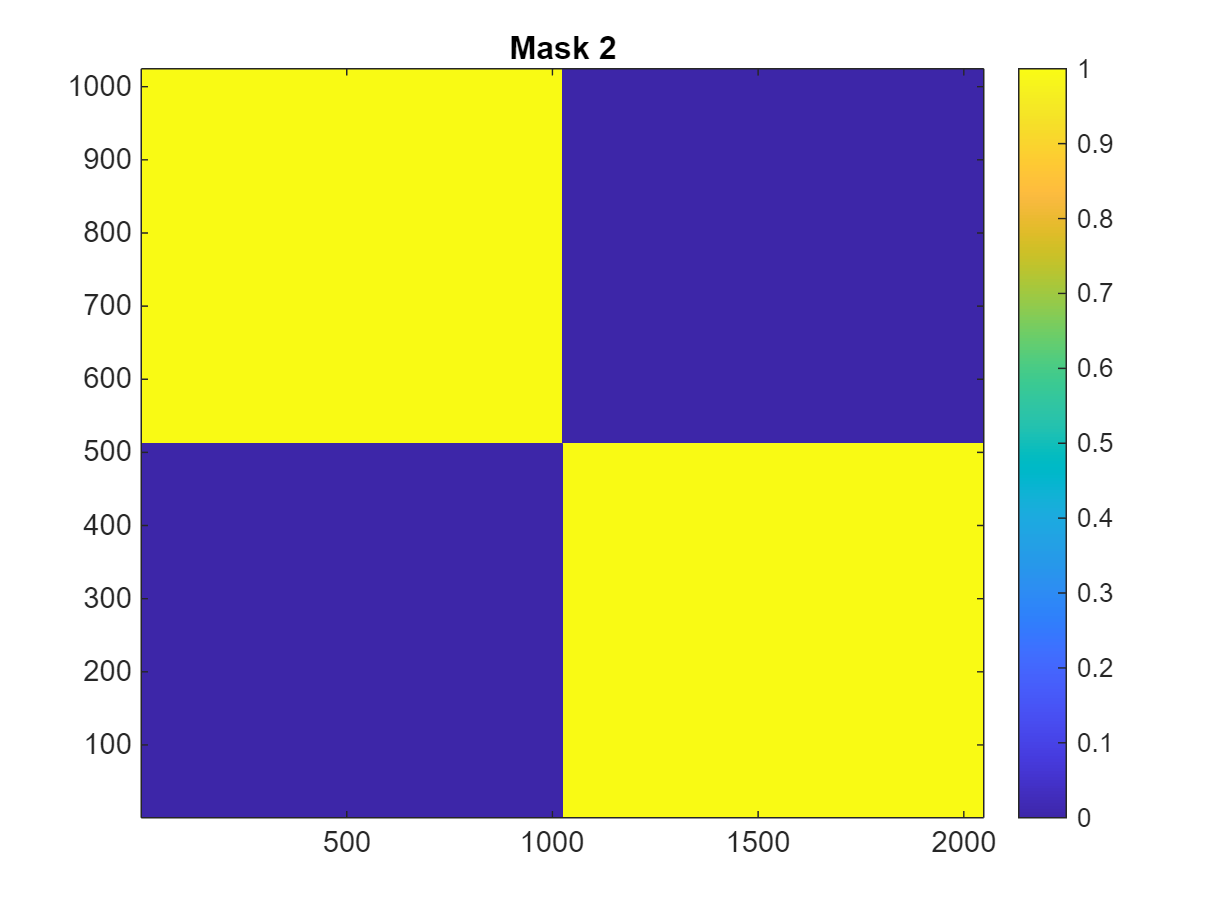


figure
imagesc(mask2)
title('Mask 2')
axis xy
colorbar

## 3) Mask-data multiplication in the freqency domain

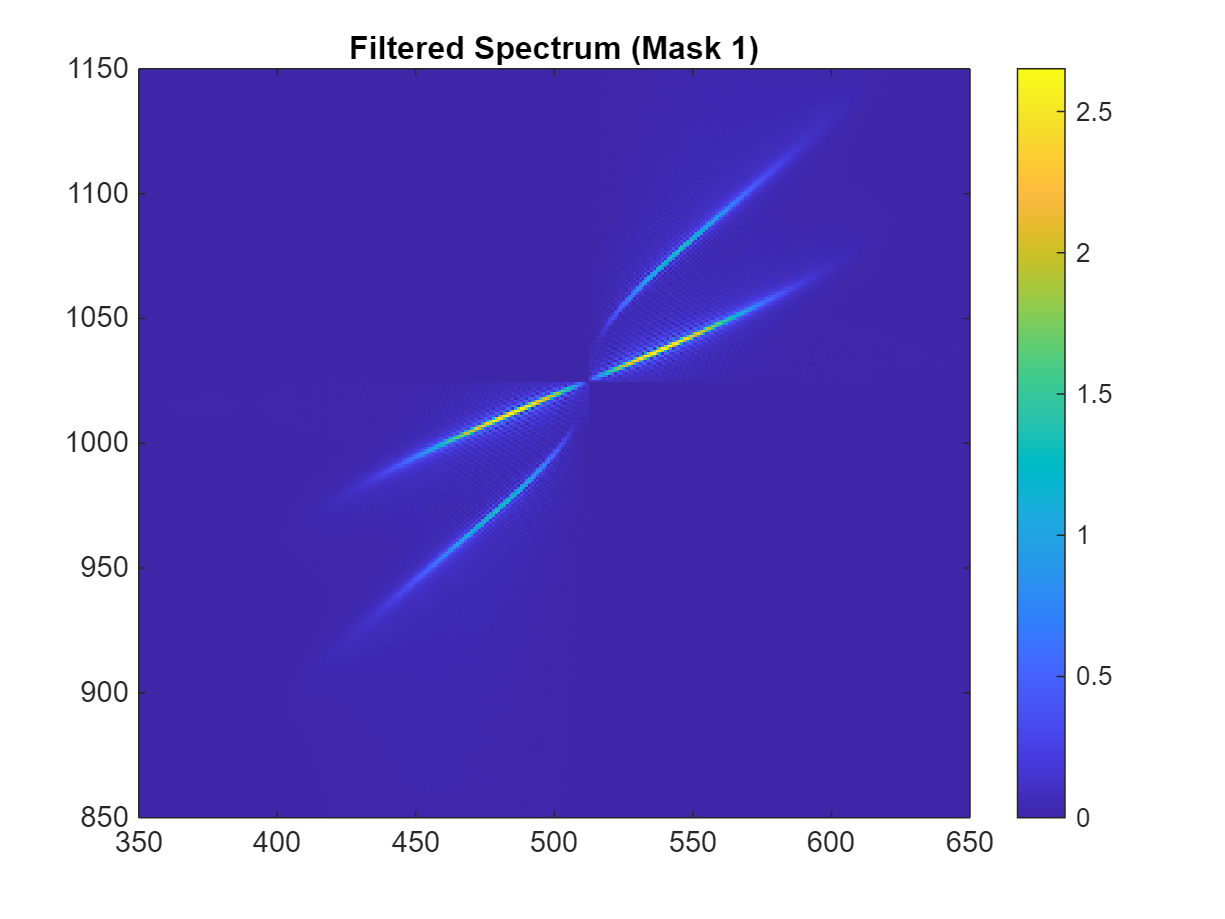

%% Apply masks in frequency domain
ans1 = X .* mask';
ans2 = X .* mask2';

figure
imagesc(abs(ans1))
axis xy
colorbar
xlim([350,650])
ylim([850,1150])
title('Filtered Spectrum (Mask 1)')

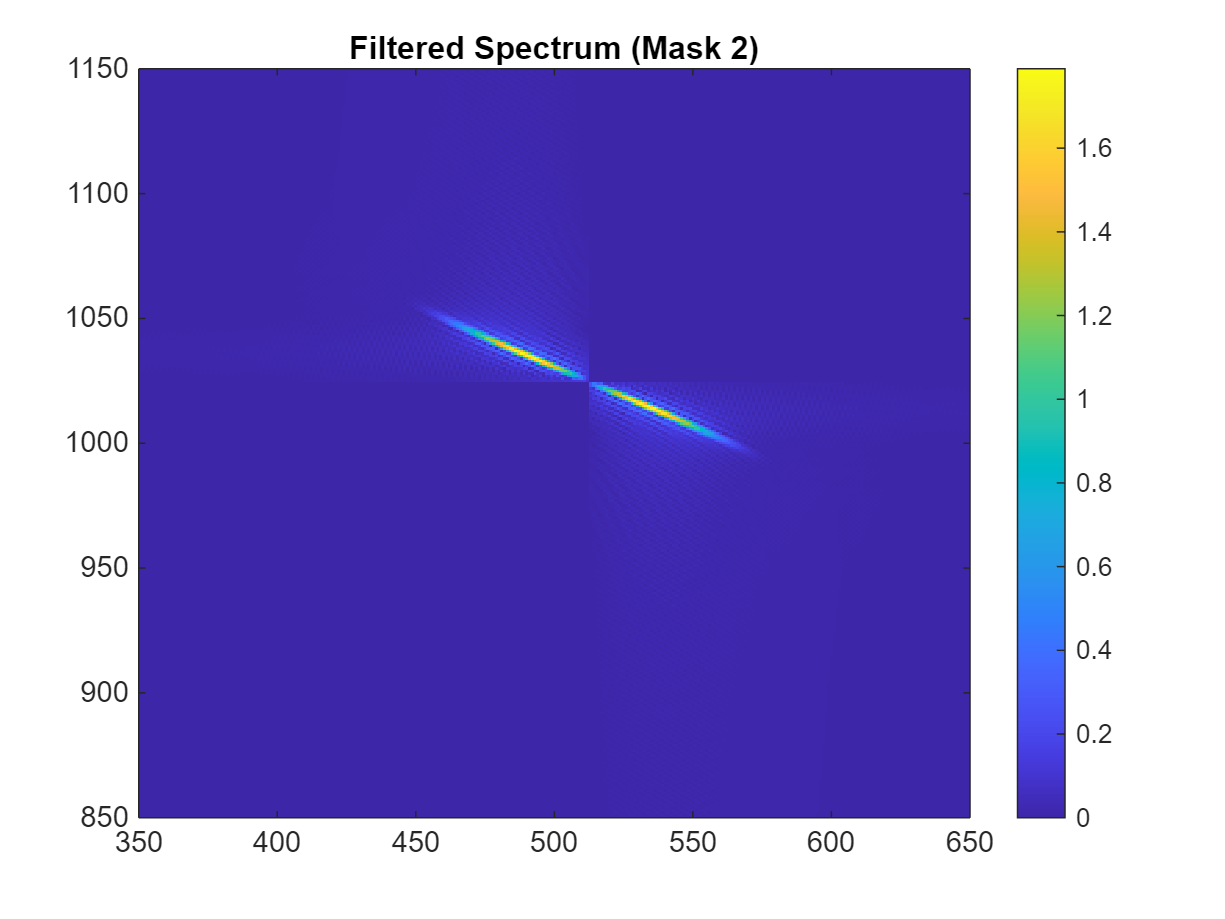


figure
imagesc(abs(ans2))
axis xy
colorbar
xlim([350,650])
ylim([850,1150])
title('Filtered Spectrum (Mask 2)')

## 3) Inverse Fourrier Transform

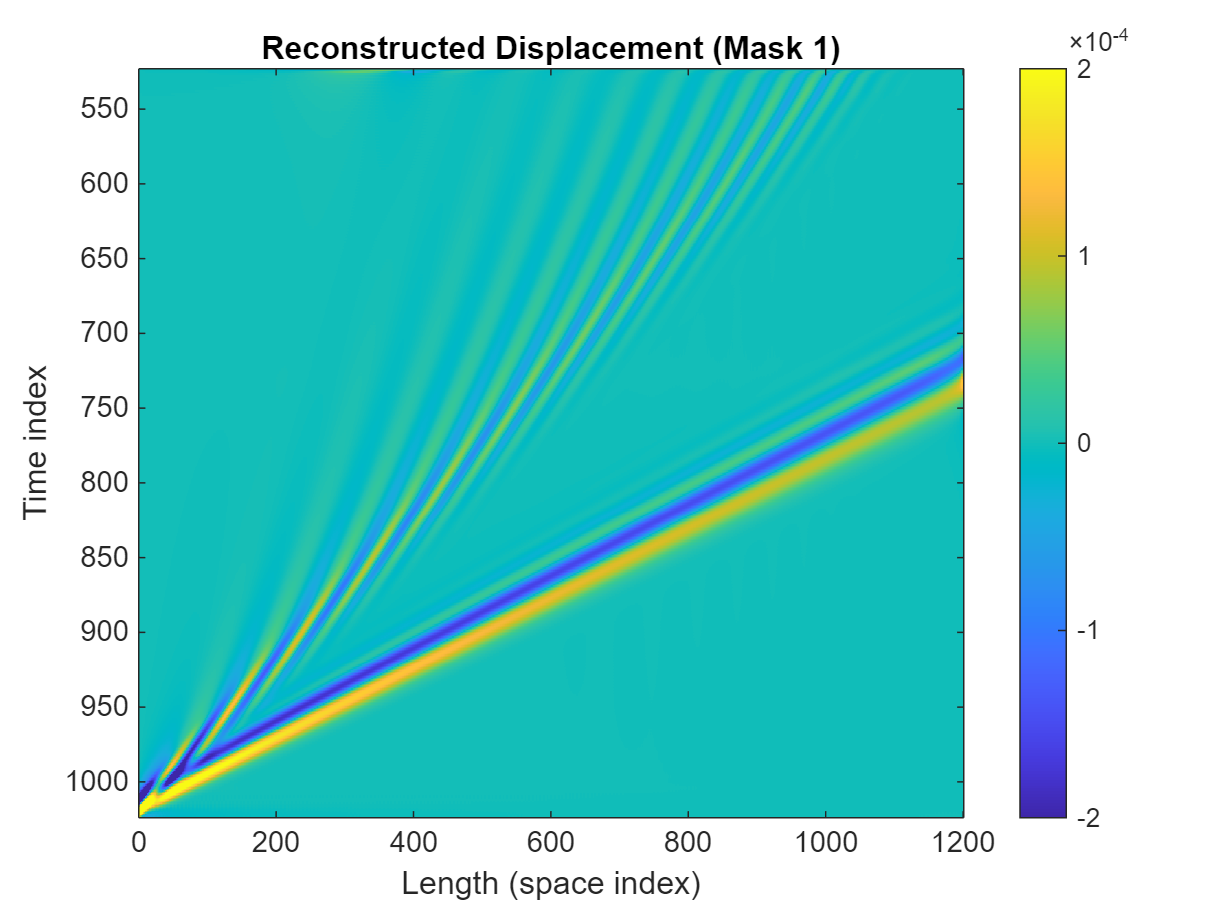

%% Inverse FFT to reconstruct filtered signals
% Undo fftshift, flip, and transpose to match original layout
X_inv  = ifftshift(ans1);
X_inv  = flip(X_inv,2);
X_inv  = X_inv.';
u_rec  = ifft2(X_inv);

X_inv2 = ifftshift(ans2);
X_inv2 = flip(X_inv2,2);
X_inv2 = X_inv2.';
u_rec2 = ifft2(X_inv2);

%% Visualize reconstructed displacement fields
figure
imagesc(flip(real(u_rec),2))
colorbar
clim([-2,2]/1e4)
xlim([0,1201])
ylim([1024-501,1024])
xlabel('Length (space index)')
ylabel('Time index')
title('Reconstructed Displacement (Mask 1)')

We observe how mask 1 succesfully deleated the horisontal wave reflected from the rod's end.

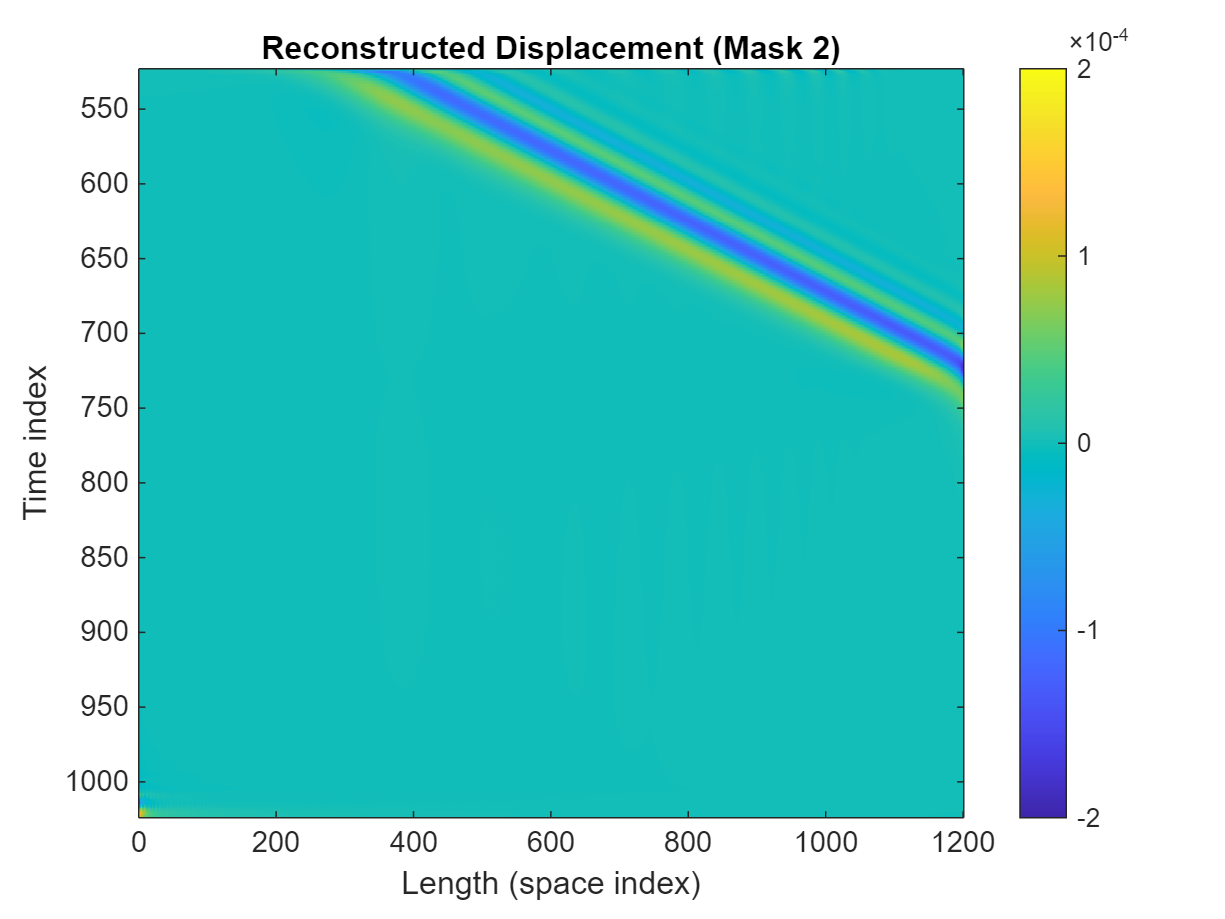


figure
imagesc(flip(real(u_rec2),2))
colorbar
clim([-2,2]/1e4)
xlim([0,1201])
ylim([1024-501,1024])
xlabel('Length (space index)')
ylabel('Time index')
title('Reconstructed Displacement (Mask 2)')

We observe how mask 2 succesfully deleated all waves propagating from the left to the right of the rod.

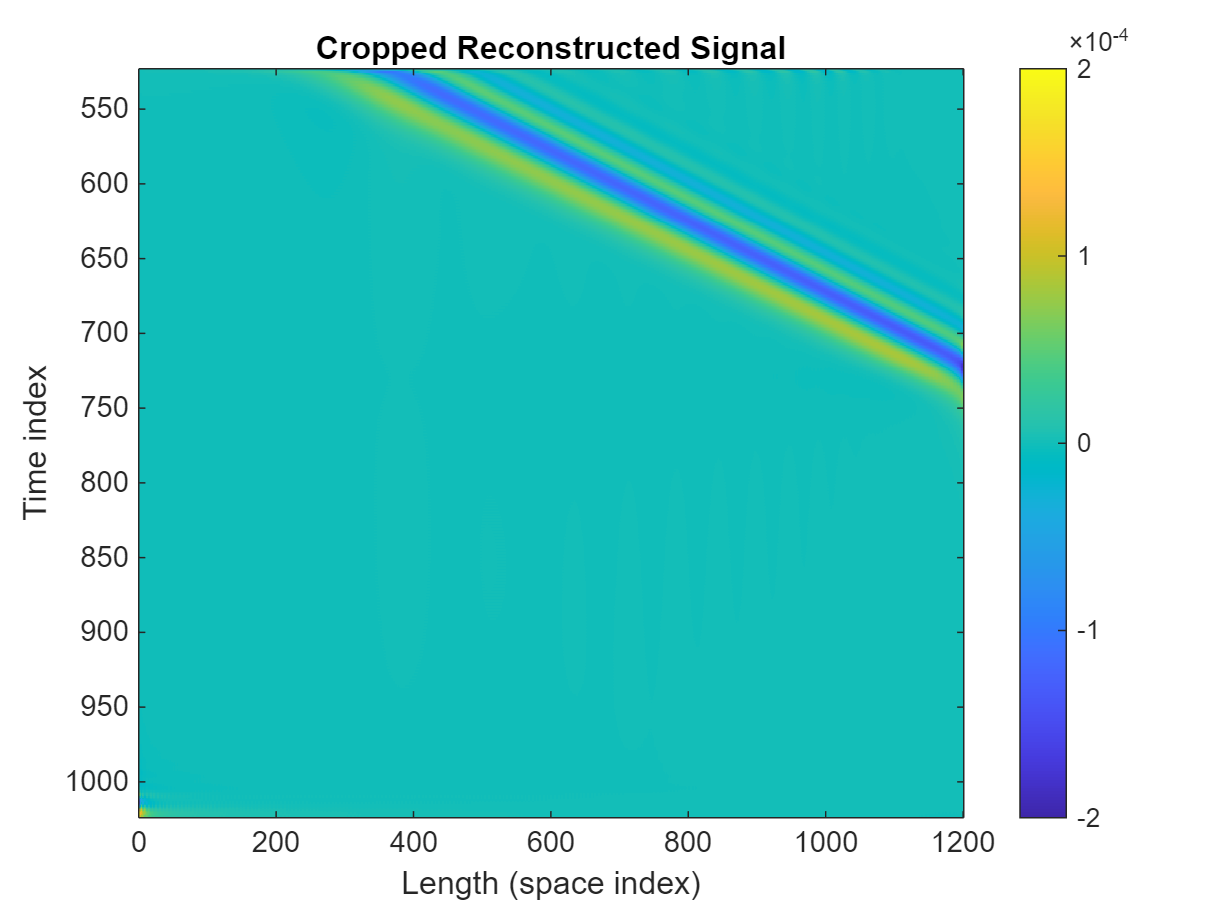

%% Remove zero-padding to recover original signal size
% After inverse FFT, crop back to original dimensions
temp  = flip(real(u_rec2),2);
temp2 = temp(1:501,1:1201);

% Compare reconstruction error
test = out - temp2;

figure
imagesc(temp)
xlim([0,1201])
ylim([1024-501,1024])
colorbar
clim([-2,2]/1e4)
xlabel('Length (space index)')
ylabel('Time index')
title('Cropped Reconstructed Signal')

Fun fact, because the mask 1 and mask 2 are opposite of eachother, given that theoretically Fourrier Transform is a lossless operation we can just apply mask 1 once in the frequency domain, apply inverse fourierr transform and subtract the result from the original to get the same result as mask 2.

## 4) Triangular mask

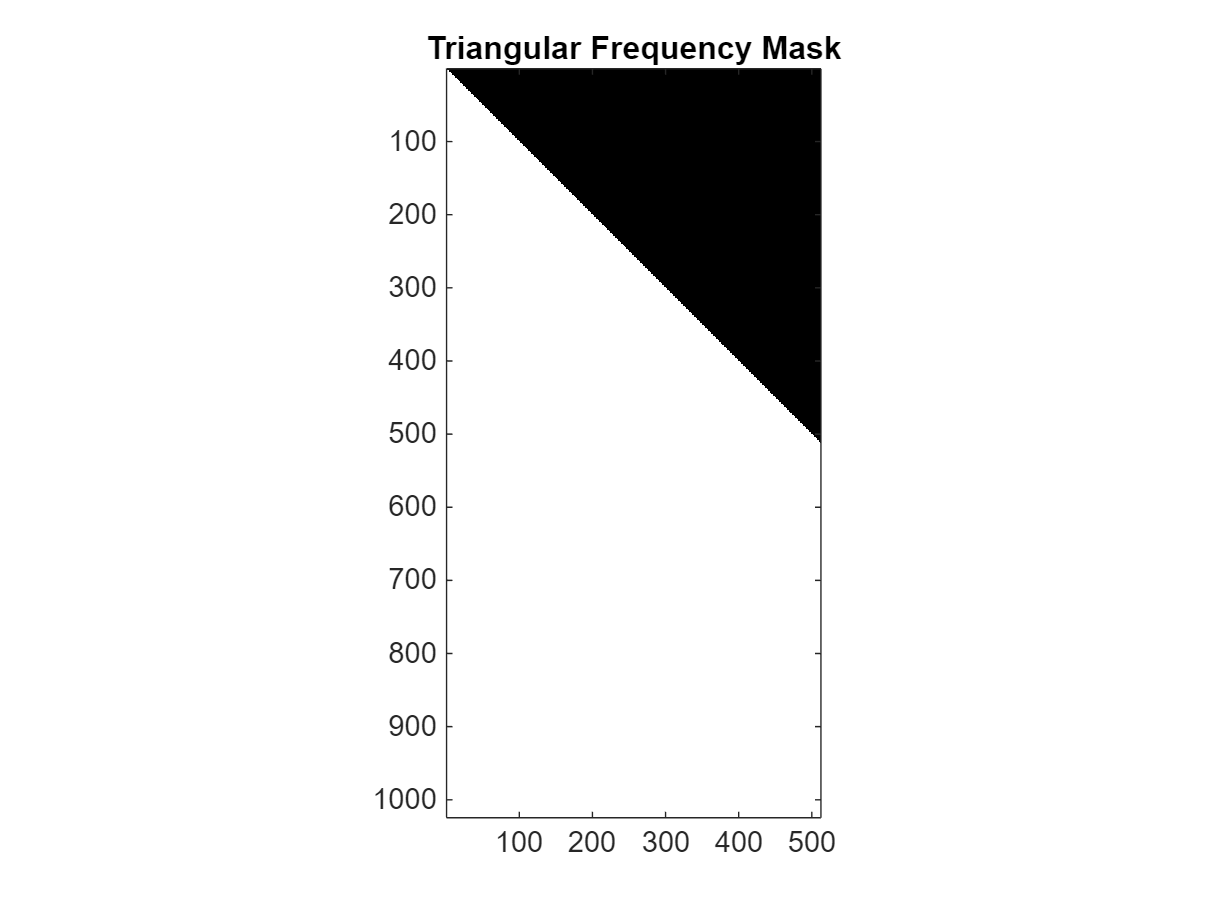

%% Create triangular mask for directional wave filtering
n = 2^11/2;   % number of rows (frequency)
m = 2^10/2;   % number of columns (wavelength)
alpha = 45;   % triangle angle in degrees

% Coordinate grid
[x, y] = meshgrid(1:m, 1:n);
Xp = x - 1;
Y  = y - 1;

% Triangle condition
alpha_rad = deg2rad(alpha);
inside_triangle = (Xp >= 0) & (Y >= 0) & (Y <= Xp * tan(alpha_rad));

% Build mask
M = ones(n,m);
M(inside_triangle) = 0;

figure
imagesc(M)
axis equal tight
colormap(gray)
title('Triangular Frequency Mask')

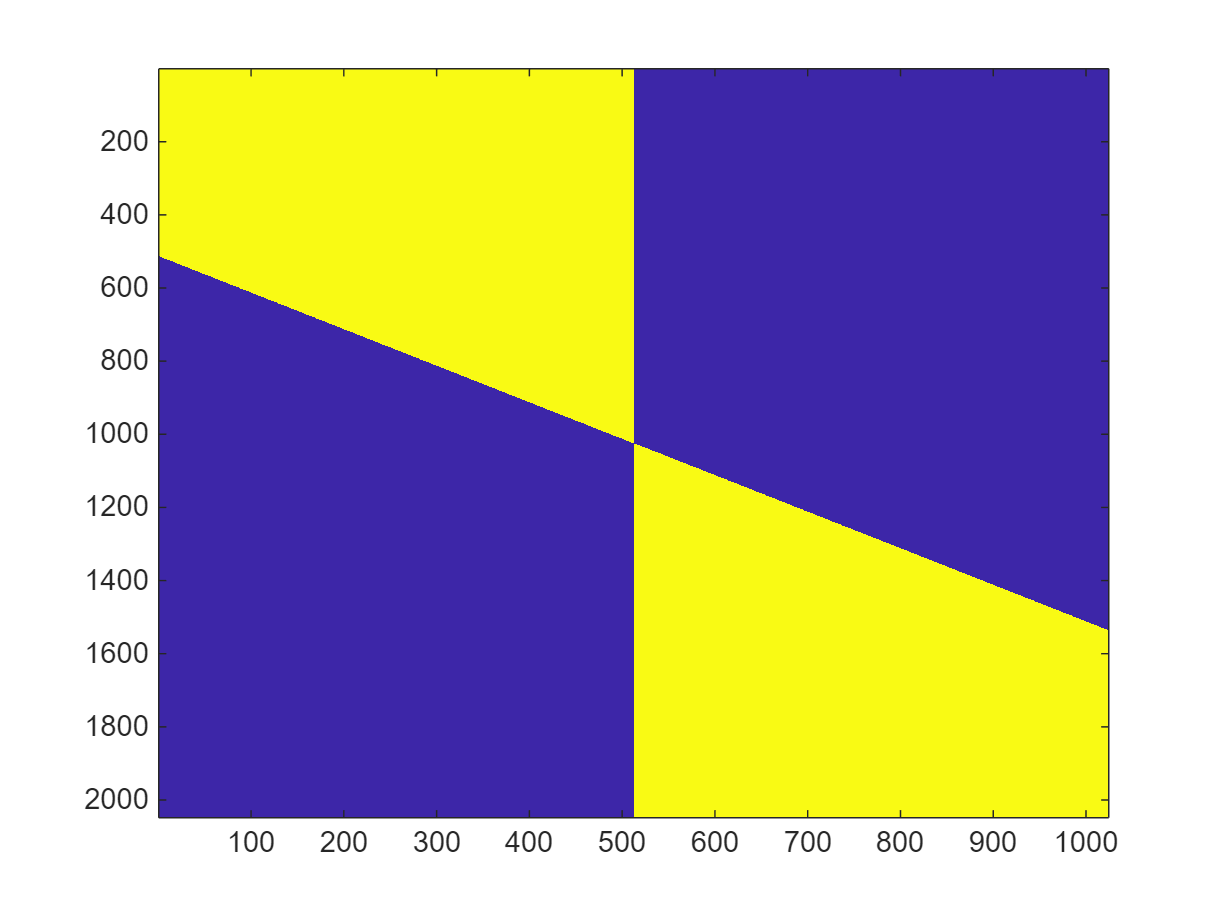


%% Extend triangle mask to full FFT size and apply
c_mask = [zeros(n,m), M(n:-1:1,:); ...
          M(:,m:-1:1), zeros(n,m)];

figure
imagesc(c_mask(end:-1:1,:))

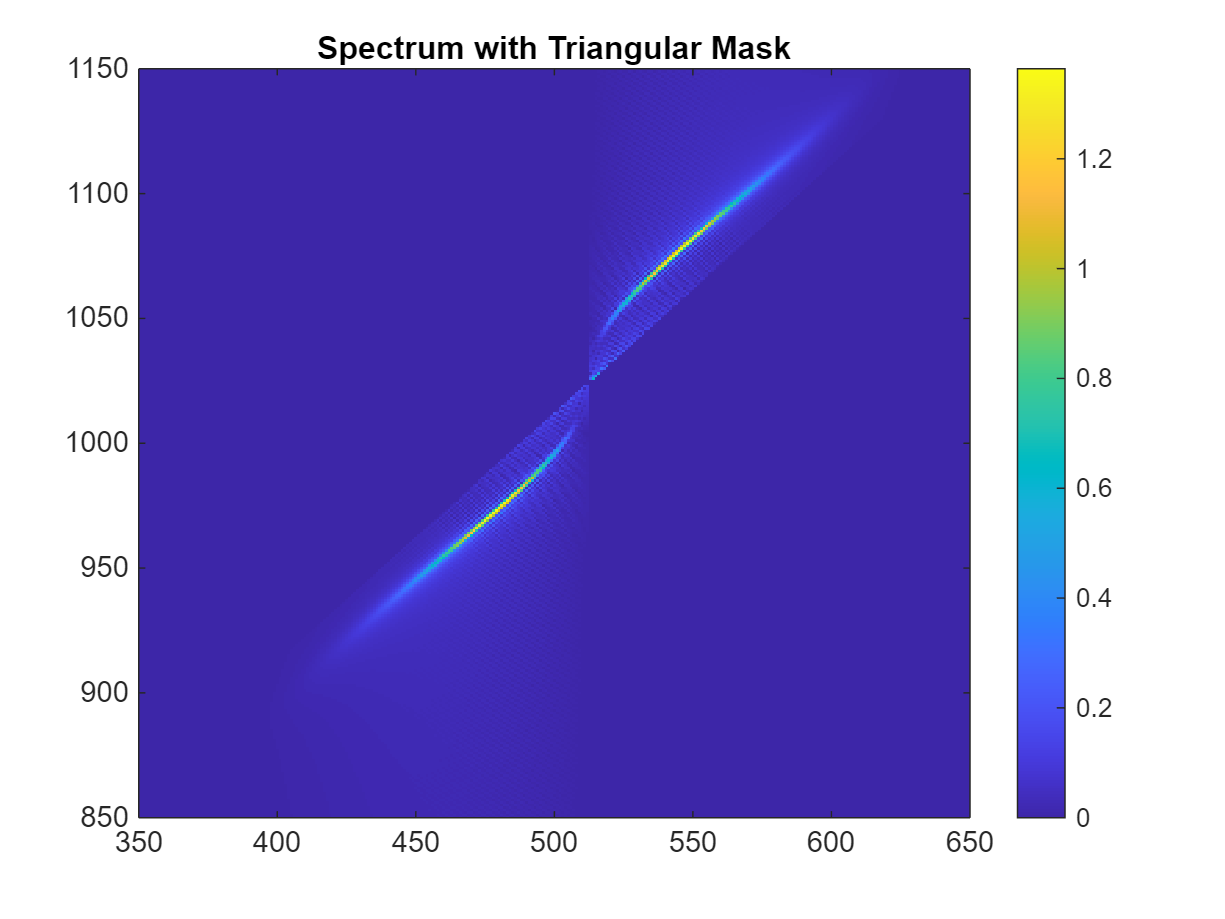


ans3 = X .* c_mask(end:-1:1,:);

figure
imagesc(abs(ans3))
axis xy
colorbar
xlim([350,650])
ylim([850,1150])
title('Spectrum with Triangular Mask')

Here we use a triangular mask to isolate only the component responsible for vertical waves reflected in the rod.

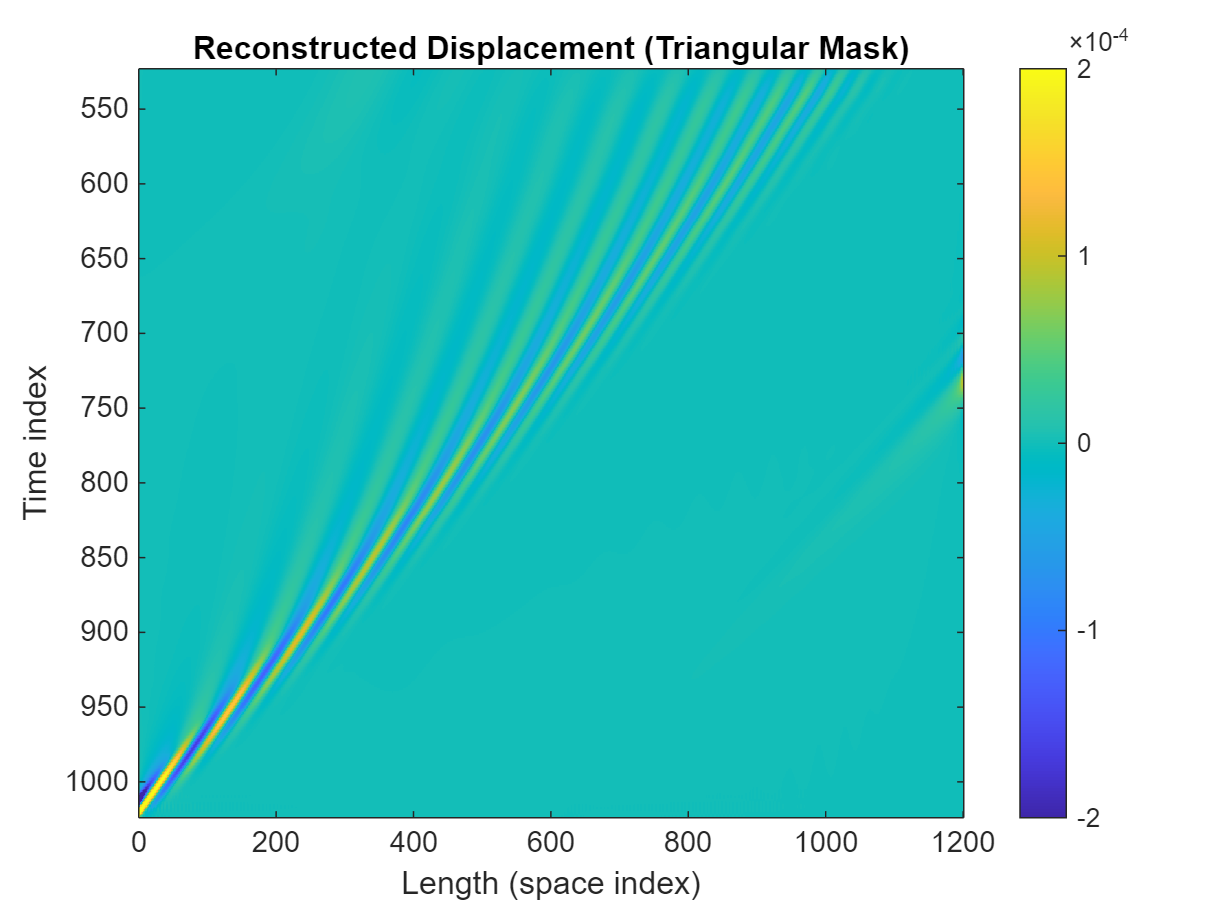


%% Inverse FFT of triangularly filtered signal
X_inv3 = ifftshift(ans3);
X_inv3 = flip(X_inv3,2);
X_inv3 = X_inv3.';
u_rec3 = ifft2(X_inv3);

figure
imagesc(flip(real(u_rec3),2))
colorbar
clim([-2,2]/1e4)
xlim([0,1201])
ylim([1024-501,1024])
xlabel('Length (space index)')
ylabel('Time index')
title('Reconstructed Displacement (Triangular Mask)')

We have successfully isolated the component responsible for vertical waves reflected in the rod.